load("C:\Users\Asus\Studia\Projekt IPS\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat")

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);

dlugosc_testu_oryginalna = 2880;

train_data = ab_diff_train_norm;
test_data = ab_diff_test_norm(1:dlugosc_testu_oryginalna);

step_length = 96

step_length = 96

% Przewidywania - BASELINE 
predictions = [zeros(step_length,1); test_data(1:end-step_length)];

mae_score = mae(test_data, predictions)

mae_score = 0.2328

mape_score = mape(test_data, predictions)

mape_score = Inf

rmse_score = rmse(test_data, predictions)

rmse_score = 0.3565

r2_classic = R2_classic(test_data, predictions)

r2_classic = -0.0606

r2_alt = R2_alt(test_data, predictions)

r2_alt = 1.0073

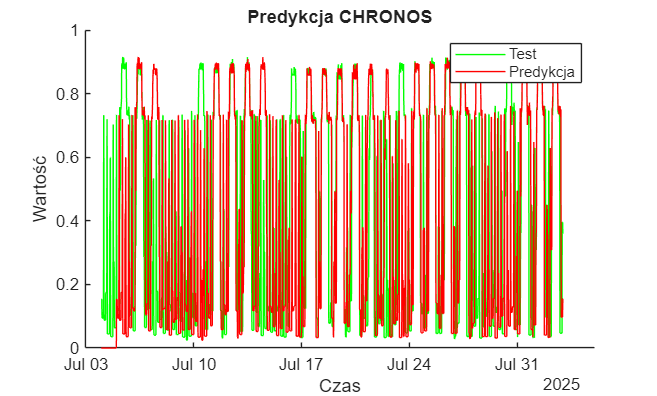


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(predictions)), ab_diff_test_norm(1:length(predictions)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(predictions)), predictions, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja CHRONOS")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
% T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
%                    ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
%                    predictions, ...
%     'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});
% 
% writetable(T_z_czasem, "pred_ab_BASELINE_month_"+ num2str(step_length)+".xlsx");